cd('/Users/sushant/Desktop/ITC/JIPITE')
filename = 'krishnafinal.xlsx';
data = readtable(filename, 'VariableNamingRule', 'preserve');

data.Properties.VariableNames = {'DateTime','X_RMS','Y_RMS','Z_RMS','XRMS_Trend','YRMS_Trend','ZRMS_Trend'};
data.DateTime = datetime(data.DateTime);

validIdx = data.X_RMS > 0 | data.Y_RMS > 0 | data.Z_RMS > 0;
data = data(validIdx, :);


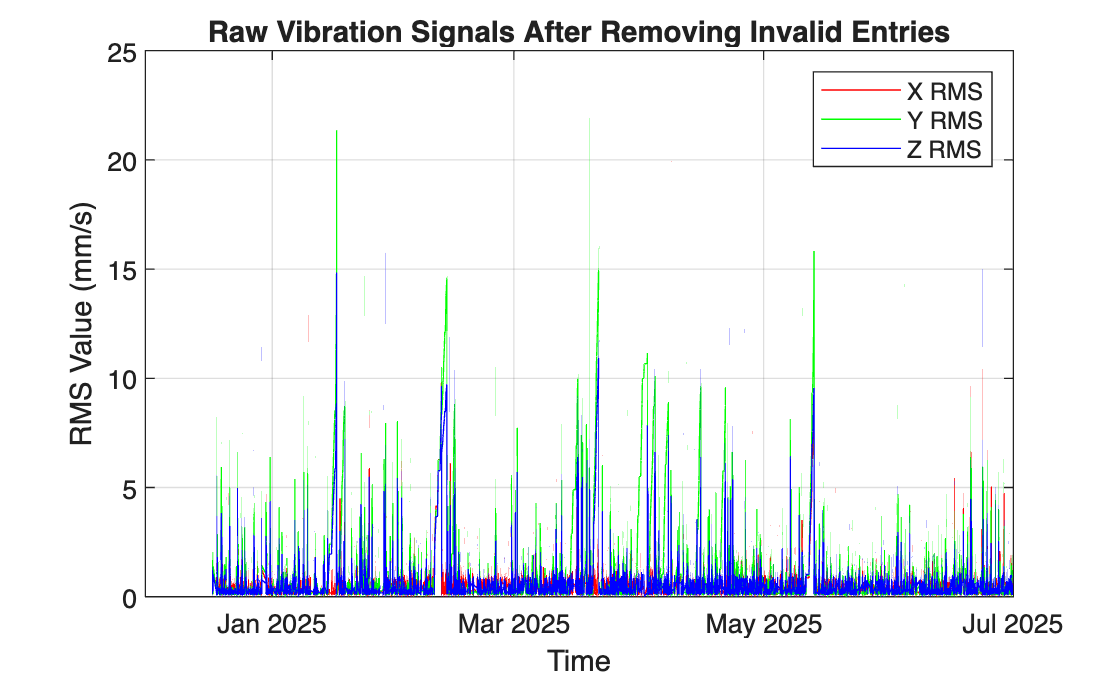

% Visualize raw vibration signals (cleaned)
figure;
plot(data.DateTime, data.X_RMS, 'r');
hold on;
plot(data.DateTime, data.Y_RMS, 'g');
plot(data.DateTime, data.Z_RMS, 'b');
xlabel('Time');
ylabel('RMS Value (mm/s)');
title('Raw Vibration Signals After Removing Invalid Entries');
legend('X RMS', 'Y RMS', 'Z RMS');
grid on;


% Step 1: Identify high-RMS indices
highRMS = data.X_RMS > 8.5 | data.Y_RMS > 8.5 | data.Z_RMS > 8.5;
highRMSIdx = find(highRMS);

fprintf("📌 High-RMS entries (X, Y, or Z > 8.5 mm/s):\n");

📌 High-RMS entries (X, Y, or Z > 8.5 mm/s):


for i = 1:length(highRMSIdx)
    idx = highRMSIdx(i);
    fprintf("Index %5d | Time: %s | X: %.2f | Y: %.2f | Z: %.2f\n", ...
        idx, string(data.DateTime(idx)), ...
        data.X_RMS(idx), data.Y_RMS(idx), data.Z_RMS(idx));
end

Index  9712 | Time: 16-Jan-2025 06:59:00 | X: 0.17 | Y: 8.51 | Z: 5.87
Index  9713 | Time: 16-Jan-2025 11:28:25 | X: 0.21 | Y: 8.53 | Z: 5.88
Index  9714 | Time: 16-Jan-2025 11:29:25 | X: 0.22 | Y: 8.55 | Z: 5.90
Index  9715 | Time: 16-Jan-2025 11:30:25 | X: 0.31 | Y: 8.57 | Z: 5.91
Index  9716 | Time: 16-Jan-2025 11:31:25 | X: 0.16 | Y: 8.59 | Z: 5.92
Index  9717 | Time: 16-Jan-2025 11:32:24 | X: 0.20 | Y: 8.61 | Z: 5.94
Index  9718 | Time: 16-Jan-2025 11:33:25 | X: 0.30 | Y: 8.64 | Z: 5.95
Index  9719 | Time: 16-Jan-2025 11:34:25 | X: 0.17 | Y: 8.66 | Z: 5.97
Index  9720 | Time: 16-Jan-2025 11:35:25 | X: 0.29 | Y: 8.68 | Z: 5.98
Index  9721 | Time: 16-Jan-2025 11:36:24 | X: 0.26 | Y: 8.70 | Z: 5.99
Index  9722 | Time: 16-Jan-2025 11:37:25 | X: 0.23 | Y: 8.72 | Z: 6.01
Index  9723 | Time: 16-Jan-2025 11:38:25 | X: 0.21 | Y: 8.74 | Z: 6.02
Index  9724 | Time: 16-Jan-2025 11:39:25 | X: 0.22 | Y: 8.77 | Z: 6.04
Index  9725 | Time: 16-Jan-2025 11:40:25 | X: 0.21 | Y: 8.79 | Z: 6.05
Index 

% Step 2: Smart ±600-sample masking only around true peaks
removeMask = false(height(data), 1);
window = 600;
lastRemovedIdx = 0;

for idx = highRMSIdx'
    % Skip if this index lies within already removed zone
    if idx - window > lastRemovedIdx
        fromIdx = max(1, idx - window);
        toIdx = min(height(data), idx + window);
        removeMask(fromIdx:toIdx) = true;
        lastRemovedIdx = toIdx;
    end
end

% Step 3: Remove those entries from data
data = data(~removeMask, :);

% Step 4: Now safely construct the features table
features = table;
features.XRMS = data.X_RMS;
features.YRMS = data.Y_RMS;
features.ZRMS = data.Z_RMS;
features.XRMS_Trend = data.XRMS_Trend;
features.YRMS_Trend = data.YRMS_Trend;
features.ZRMS_Trend = data.ZRMS_Trend;
features.MagRMS = sqrt(data.X_RMS.^2 + data.Y_RMS.^2 + data.Z_RMS.^2);
features.dXRMS = [NaN; diff(data.X_RMS)];
features.dYRMS = [NaN; diff(data.Y_RMS)];
features.dZRMS = [NaN; diff(data.Z_RMS)];

% Remove missing values from both features and data ⬅️ NEW LINE
missingMask = any(ismissing(features), 2);
features = features(~missingMask, :);
data = data(~missingMask, :);  % align data table with features

% ---- Normalize using training-only range ----
X_full = features{:,:};
numTrain = round(0.5 * size(X_full, 1));
train_min = min(X_full(1:numTrain, :));
train_max = max(X_full(1:numTrain, :));

X = (X_full - train_min) ./ (train_max - train_min);
X = max(min(X, 1), 0);  % clamp to [0,1]

% Optional detrending
% X = detrend(X);
% X = diff(X);

numTrain = round(0.5 * size(X, 1));
XTrain = {X(1:numTrain, :)'};  
Xseq   = {X'};                         

% Autoencoder
layers = [
    sequenceInputLayer(size(X, 2))
    fullyConnectedLayer(32)
    reluLayer
    fullyConnectedLayer(16)
    reluLayer
    fullyConnectedLayer(32)
    reluLayer
    fullyConnectedLayer(size(X,2))
    regressionLayer
];

options = trainingOptions('adam', ...
    'MaxEpochs', 120, ...
    'MiniBatchSize', 32, ...
    'InitialLearnRate', 1e-3, ...
    'Shuffle', 'every-epoch', ...
    'Plots', 'training-progress', ...
    'Verbose', false);

% Train and Predict
net = trainNetwork(XTrain, XTrain, layers, options);


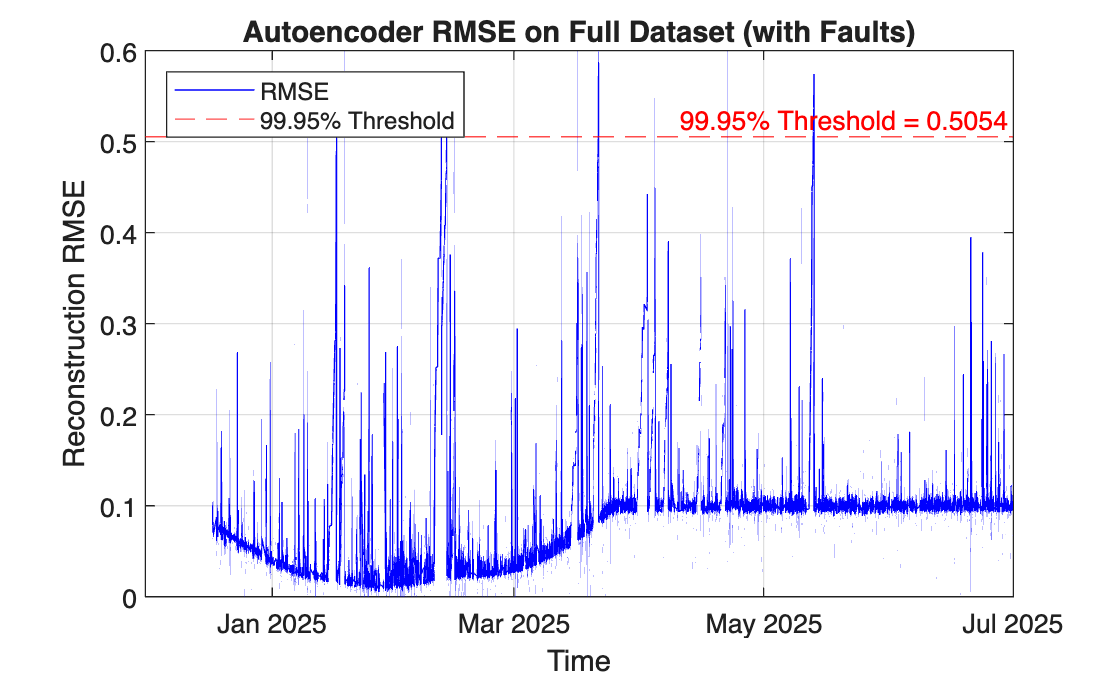

% 🧠 Assumes 'net' is your trained autoencoder from healthy data

% Reload full data (only removing zero-RMS entries)
filename = 'krishnafinal.xlsx';
dataFull = readtable(filename, 'VariableNamingRule', 'preserve');
dataFull.Properties.VariableNames = {'DateTime','X_RMS','Y_RMS','Z_RMS','XRMS_Trend','YRMS_Trend','ZRMS_Trend'};
dataFull.DateTime = datetime(dataFull.DateTime);

validIdx = dataFull.X_RMS > 0 | dataFull.Y_RMS > 0 | dataFull.Z_RMS > 0;
dataFull = dataFull(validIdx, :);  % ⚠️ only remove invalid, keep faults

% Feature engineering
featuresFull = table;
featuresFull.XRMS = dataFull.X_RMS;
featuresFull.YRMS = dataFull.Y_RMS;
featuresFull.ZRMS = dataFull.Z_RMS;
featuresFull.XRMS_Trend = dataFull.XRMS_Trend;
featuresFull.YRMS_Trend = dataFull.YRMS_Trend;
featuresFull.ZRMS_Trend = dataFull.ZRMS_Trend;
featuresFull.MagRMS = sqrt(dataFull.X_RMS.^2 + dataFull.Y_RMS.^2 + dataFull.Z_RMS.^2);
featuresFull.dXRMS = [NaN; diff(dataFull.X_RMS)];
featuresFull.dYRMS = [NaN; diff(dataFull.Y_RMS)];
featuresFull.dZRMS = [NaN; diff(dataFull.Z_RMS)];
featuresFull = rmmissing(featuresFull);
dataFull = dataFull(end - height(featuresFull) + 1 : end, :);  % realign time

% Normalize using old training min-max
X_fullRaw = featuresFull{:,:};
X_fullNorm = (X_fullRaw - train_min) ./ (train_max - train_min);
X_fullNorm = max(min(X_fullNorm, 1), 0);

% Predict with autoencoder
X_testSeq = {X_fullNorm'};
Y_testPred = predict(net, X_testSeq);
reconLoss_full_full = sqrt(mean((X_testSeq{1} - Y_testPred{1}).^2, 1));
timestamps_full_full = dataFull.DateTime(end - numel(reconLoss_full_full) + 1:end);

% Plot reconstruction loss over time
figure;
plot(timestamps_full_full, reconLoss_full_full, 'b');
xlabel('Time');
ylabel('Reconstruction RMSE');
title('Autoencoder RMSE on Full Dataset (with Faults)');
grid on;

% Optional: Add threshold from clean RMSE
threshold = prctile(reconLoss_full_full(1:round(0.5*end)), 99.95);
yline(threshold, '--r', sprintf('99.95%% Threshold = %.4f', threshold));

legend('RMSE', '99.95% Threshold', 'Location', 'northwest');

% Assuming `reconLoss_full` is your RMSE vector
% and `threshold` is already defined (e.g., using prctile)

% Count how many values exceed the threshold
numAboveThreshold = sum(reconLoss_full_full > threshold);

% Print the result
fprintf('🔍 Number of RMSE values above threshold (%.4f): %d\n', threshold, numAboveThreshold);

🔍 Number of RMSE values above threshold (0.5054): 98


% Get indices where RMSE > threshold
exceedingIdx = find(reconLoss_full_full > threshold);

% Optionally get the corresponding timestamps_full
exceedingTimes = timestamps_full_full(exceedingIdx);  % assuming `timestamps_full` aligns with `reconLoss_full`

% Display sample of them
disp("Sample timestamps_full where RMSE exceeded threshold:");

Sample timestamps_full where RMSE exceeded threshold:


disp(exceedingTimes);  % print first 10 for brevity

   16-Jan-2025 17:21:35
   11-Feb-2025 07:57:05
   12-Feb-2025 15:12:07
   21-Mar-2025 15:23:39
   21-Mar-2025 15:28:39
   21-Mar-2025 15:33:38
   21-Mar-2025 15:38:39
   21-Mar-2025 15:43:39
   21-Mar-2025 15:48:39
   21-Mar-2025 15:53:38
   21-Mar-2025 15:58:39
   21-Mar-2025 16:10:40
   21-Mar-2025 16:30:40
   21-Mar-2025 16:35:40
   21-Mar-2025 16:40:40
   21-Mar-2025 16:45:40
   21-Mar-2025 16:50:40
   13-May-2025 03:29:47
   13-May-2025 03:30:47
   13-May-2025 03:31:47
   13-May-2025 03:32:47
   13-May-2025 03:33:47
   13-May-2025 03:34:47
   13-May-2025 03:35:47
   13-May-2025 03:36:47
   13-May-2025 03:37:47
   13-May-2025 03:38:47
   13-May-2025 03:43:48
   13-May-2025 03:44:48
   13-May-2025 03:45:49
   13-May-2025 03:50:49
   13-May-2025 03:55:49
   13-May-2025 04:00:49
   13-May-2025 04:05:49
   13-May-2025 04:06:50
   13-May-2025 04:07:50
   13-May-2025 04:08:49
   13-May-2025 04:13:51
   13-May-2025 04:14:52
   13-May-2025 04:15:53
   13-May-2025 04:20:53
   13-May-2025 0

%% --------------------------------------------
% 📈 Predicting RMSE 600 Steps Ahead from Sliding Windows (LSTM)
% --------------------------------------------

% Use original unsmoothed RMSE if needed
smoothRMSE = double(reconLoss_full_full);  % or reconLoss_full directly

% Split into train and forecast regions
rmseTrain = smoothRMSE(1:round(0.5*length(smoothRMSE)));
rmseForecastRegion = smoothRMSE(round(0.5*length(smoothRMSE))+1:end);

% Parameters
windowSize = 100;
forecastHorizon = 600;
stride = 30;
numForecasts = floor((length(rmseForecastRegion) - windowSize - forecastHorizon) / stride) + 1;

% Prepare LSTM training dataset
X_lstm = {};
Y_lstm = {};

for i = 1:(length(rmseTrain) - windowSize)
    X_lstm{end+1} = rmseTrain(i : i + windowSize - 1);
    Y_lstm{end+1} = rmseTrain(i + windowSize);
end

X_lstm = X_lstm';
Y_lstm = cell2mat(Y_lstm');

% Define LSTM layers
layersLSTM = [
    sequenceInputLayer(1)
    lstmLayer(50, 'OutputMode','last')
    fullyConnectedLayer(1)
    regressionLayer
];

optionsLSTM = trainingOptions('adam', ...
    'MaxEpochs', 100, ...
    'MiniBatchSize', 32, ...
    'InitialLearnRate', 0.005, ...
    'GradientThreshold', 1, ...
    'Shuffle', 'every-epoch', ...
    'Verbose', false);

fprintf("⏳ Training LSTM on RMSE (first 50%%)...\n");

⏳ Training LSTM on RMSE (first 50%)...


netLSTM = trainNetwork(X_lstm, Y_lstm, layersLSTM, optionsLSTM);
fprintf("✅ LSTM training complete.\n");

✅ LSTM training complete.



% Prepare table to store results
forecast600Results_LSTM = table('Size', [numForecasts 3], ...
    'VariableTypes', {'double','datetime','cell'}, ...
    'VariableNames', {'WindowIndex','WindowStartTime','AllForecastedSteps'});

fprintf("📈 Starting %d rolling forecasts using LSTM...\n", numForecasts);

📈 Starting 1122 rolling forecasts using LSTM...



% Rolling forecasting
for i = 1:numForecasts
    idxStart = (i-1)*stride + 1;
    idxEnd = idxStart + windowSize - 1;

    inputSeq = rmseForecastRegion(idxStart:idxEnd);
    inputSeq = inputSeq(:)';  % [1 × windowSize]

    forecastSteps = zeros(1, forecastHorizon);
    for j = 1:forecastHorizon
        nextVal = predict(netLSTM, {inputSeq});
        forecastSteps(j) = double(nextVal);
        inputSeq = [inputSeq(2:end), double(nextVal)];
    end

    forecast600Results_LSTM.WindowIndex(i) = i;
    forecast600Results_LSTM.WindowStartTime(i) = timestamps_full_full(round(0.5*length(smoothRMSE)) + idxStart);
    forecast600Results_LSTM.AllForecastedSteps{i} = forecastSteps(:)';
    fprintf("On forecast number %d\n", i);
end

On forecast number 1
On forecast number 2
On forecast number 3
On forecast number 4
On forecast number 5
On forecast number 6
On forecast number 7
On forecast number 8
On forecast number 9
On forecast number 10
On forecast number 11
On forecast number 12
On forecast number 13
On forecast number 14
On forecast number 15
On forecast number 16
On forecast number 17
On forecast number 18
On forecast number 19
On forecast number 20
On forecast number 21
On forecast number 22
On forecast number 23
On forecast number 24
On forecast number 25
On forecast number 26
On forecast number 27
On forecast number 28
On forecast number 29
On forecast number 30
On forecast number 31
On forecast number 32
On forecast number 33
On forecast number 34
On forecast number 35
On forecast number 36
On forecast number 37
On forecast number 38
On forecast number 39
On forecast number 40
On forecast number 41
On forecast number 42
On forecast number 43
On forecast number 44
On forecast number 45
On forecast number 


fprintf("✅ LSTM forecasting complete. Sample results:\n");

✅ LSTM forecasting complete. Sample results:


disp(forecast600Results_LSTM(1:10, :));

    WindowIndex      WindowStartTime                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                  


% 📌 Define your threshold (adjust as needed)
myThreshold = threshold/1.5;

% 🔢 Compute max forecasted RMSE for each row
forecast600Results_LSTM.MaxForecastedValue = cellfun(@max, forecast600Results_LSTM.AllForecastedSteps);

% 📊 Sort the table by max forecasted value (descending)
forecast600Results_LSTM = sortrows(forecast600Results_LSTM, 'MaxForecastedValue', 'descend');

% 🧠 Preallocate column for indices exceeding threshold
forecast600Results_LSTM.ExceedIndices = cell(height(forecast600Results_LSTM), 1);

% 🔁 Loop to populate ExceedIndices
for i = 1:height(forecast600Results_LSTM)
    forecastVec = forecast600Results_LSTM.AllForecastedSteps{i};
    exceedIdx = find(forecastVec > myThreshold);

    if isempty(exceedIdx)
        forecast600Results_LSTM.ExceedIndices{i} = NaN;
    else
        forecast600Results_LSTM.ExceedIndices{i} = exceedIdx;
    end
end

% 🧮 Find rows where first exceedance index is not 1
nonOneExceedRows = false(height(forecast600Results_LSTM), 1);

for i = 1:height(forecast600Results_LSTM)
    idx = forecast600Results_LSTM.ExceedIndices{i};
    if isnumeric(idx) && all(~isnan(idx)) && idx(1) ~= 1
        nonOneExceedRows(i) = true;
    end
end

% 📊 Extract and display rows where exceedance doesn't start at step 1
filteredResults_LSTM = forecast600Results_LSTM(nonOneExceedRows, ...
    {'WindowIndex','WindowStartTime','MaxForecastedValue','ExceedIndices'});

fprintf("🔢 Number of LSTM forecasts where threshold exceedance didn't start at step 1: %d\n", height(filteredResults_LSTM));

🔢 Number of LSTM forecasts where threshold exceedance didn't start at step 1: 1112


disp(filteredResults_LSTM);

    WindowIndex      WindowStartTime       MaxForecastedValue                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                        